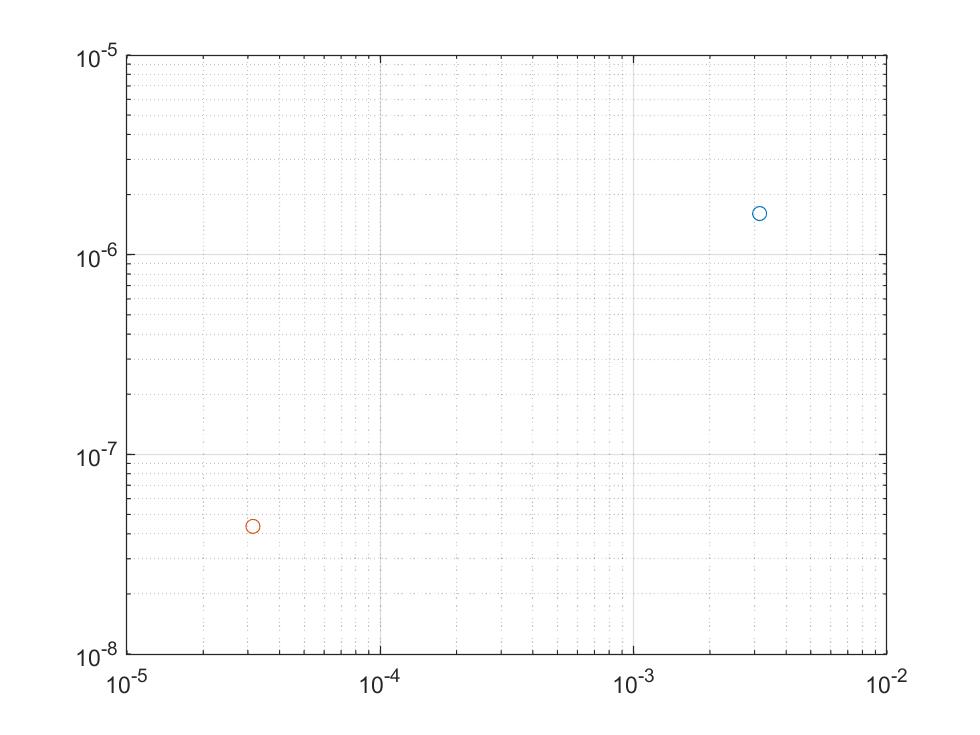

f =@(x) (cos((pi.*x.^2)./2));

a = 0;
b = pi;

n = [10^3,10^5];

I1 = composite_trapezoid(f,a,b,n(1,1));
I2 = composite_trapezoid(f,a,b,n(1,2));

% eans = fresnelc(pi);
eans = 5.236985e-01;

Err1 = abs(eans-I1);
Err2 = abs(eans-I2);

h1 = (b-a)/n(1,1);
h2 = (b-a)/n(1,2);

loglog(h1,Err1,'o-',h2,Err2,'o-');
grid on;


% The error appears to be decreasing as the number of subintervals increases, which is
% expected as the the accuracy increases.


function [I] = composite_trapezoid(f,a,b,n)
    h = (b-a)/n;
    x = a:h:b;
    temp = 0;
    for i = 1:n
        temp = temp + ((f(x(1,i))+f(x(1,i+1))).*h)./2;
    end
    I = temp;
end
